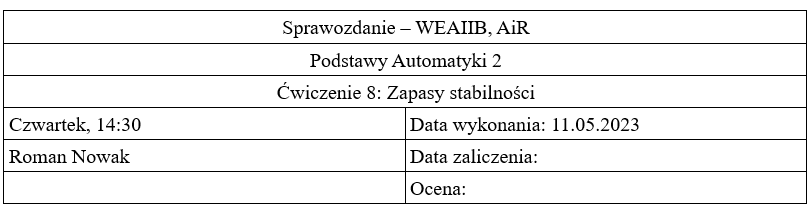

Ćwiczenie ma celu przeanalizowanie wpływu paremetrów regulatora PID na stabilność układu - wartości zapasów modułu i fazy

Analizę przeprowadzamy dla czterech obiektów o podanych niżej transmitancjach.

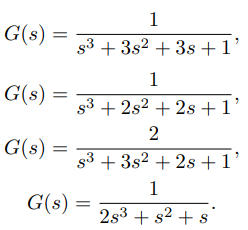

G1 = tf([1], [1 3 3 1]);
G2 = tf([1], [1 2 2 1]);
G3 = tf([1], [1 3 2 1]);
G4 = tf([1], [2 1 1 0]);

k1 = 8.0011 / 2

k1 = 4.0006

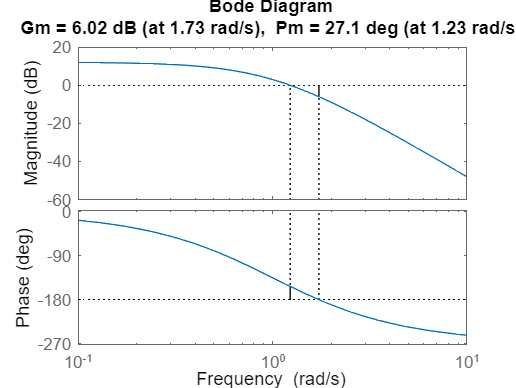

zapas_modulu = 2.0000

zapas_fazy = 27.1360

zapasy(G1, k1, 0, 0);

k2 = 3 / 2

k2 = 1.5000

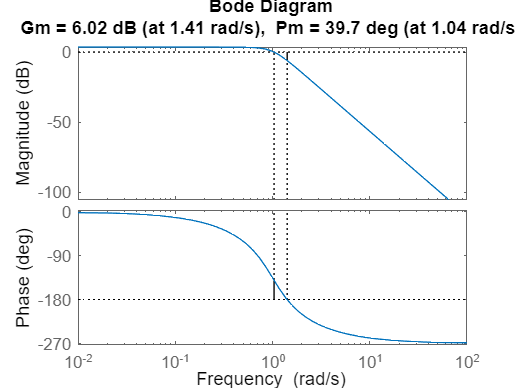

zapas_modulu = 2.0000

zapas_fazy = 39.6836

zapasy(G2, k2, 0, 0);

k3 = 5.0029 / 2

k3 = 2.5015

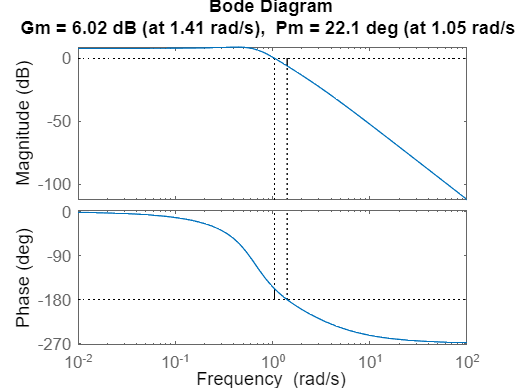

zapas_modulu = 2.0000

zapas_fazy = 22.0773

zapasy(G3, k3, 0, 0);

k4 = 0.5 / 2

k4 = 0.2500

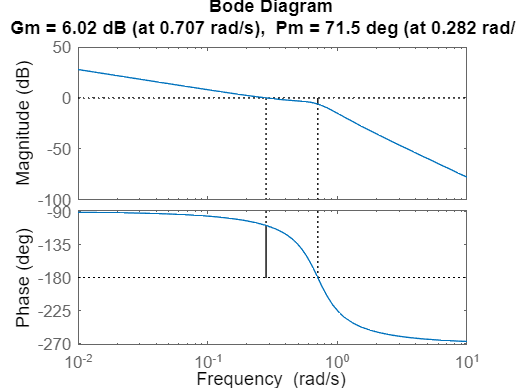

zapas_modulu = 2.0000

zapas_fazy = 71.4778

zapasy(G4, k4, 0, 0);

alfa = 0.1

alfa = 0.1000

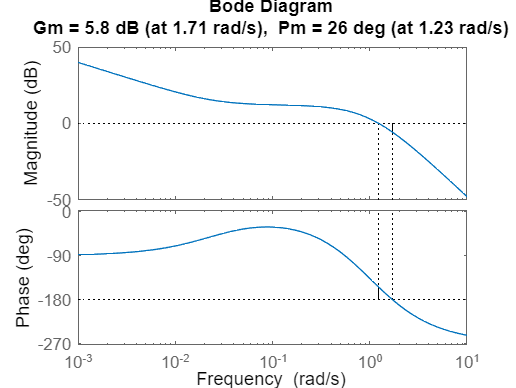

zapas_modulu = 1.9502

zapas_fazy = 25.9651

zapasy(G1, k1, alfa, 0);

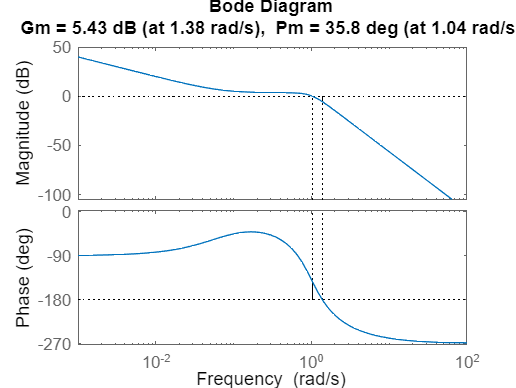

zapas_modulu = 1.8690

zapas_fazy = 35.8373

zapasy(G2, k2, alfa, 0);

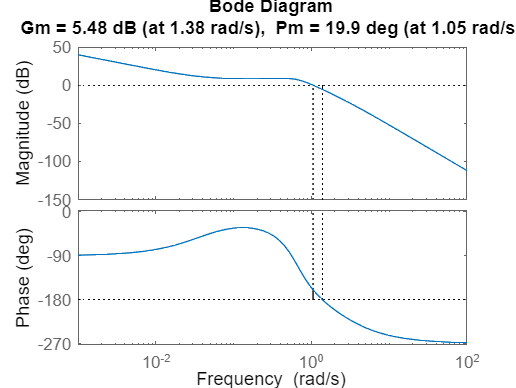

zapas_modulu = 1.8802

zapas_fazy = 19.8733

zapasy(G3, k3, alfa, 0);

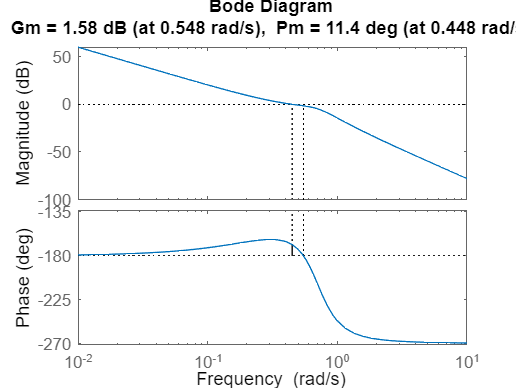

zapas_modulu = 1.2000

zapas_fazy = 11.4055

zapasy(G4, k4, alfa, 0);

alfa = 1

alfa = 1

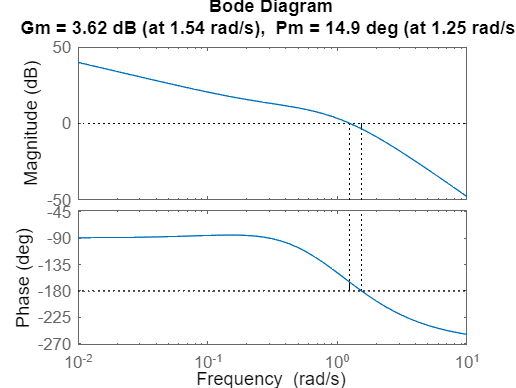

zapas_modulu = 1.5175

zapas_fazy = 14.8847

zapasy(G1, k1, alfa, 0);

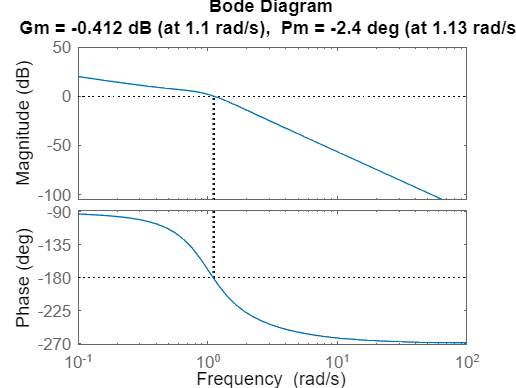

zapas_modulu = 0.9537

zapas_fazy = -2.4014

zapasy(G2, k2, alfa, 0);

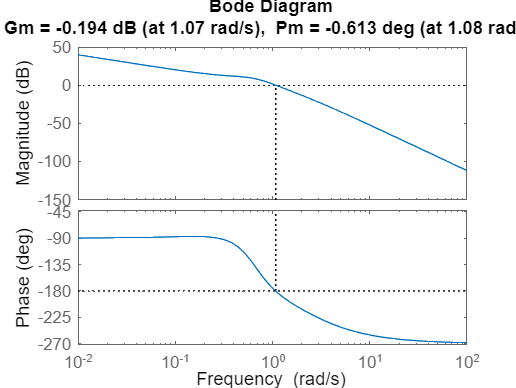

zapas_modulu = 0.9779

zapas_fazy = -0.6135

zapasy(G3, k3, alfa, 0);

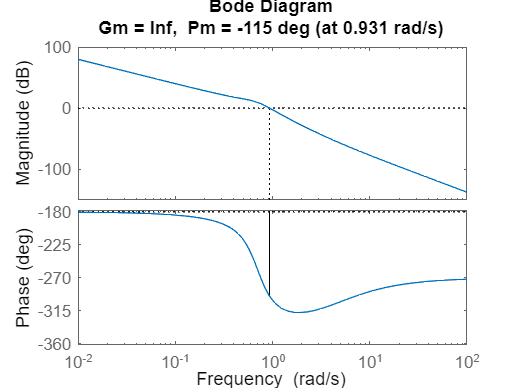

zapas_modulu = 0

zapas_fazy = -115.1196

zapasy(G4, k4, alfa, 0);

beta = 0.5

beta = 0.5000

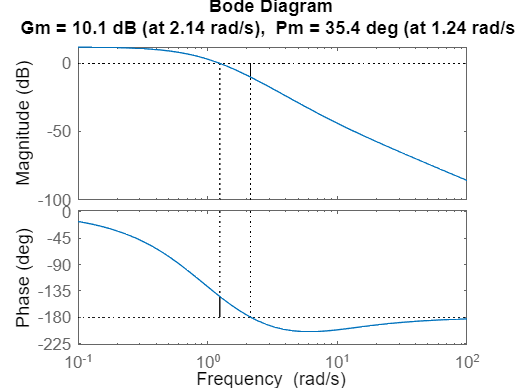

zapas_modulu = 3.1993

zapas_fazy = 35.4024

zapasy(G1, k1, 0, beta);

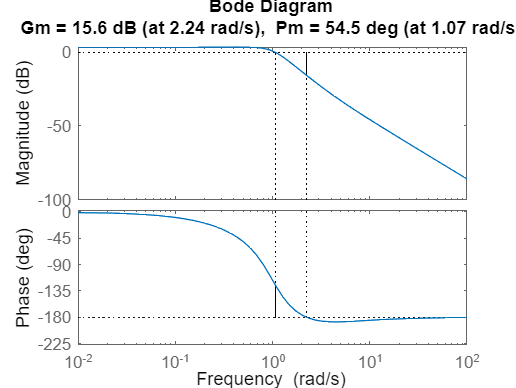

zapas_modulu = 6.0002

zapas_fazy = 54.4706

zapasy(G2, k2, 0, beta);

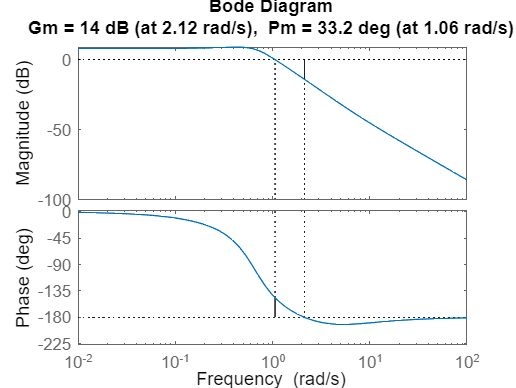

zapas_modulu = 4.9928

zapas_fazy = 33.2205

zapasy(G3, k3, 0, beta);

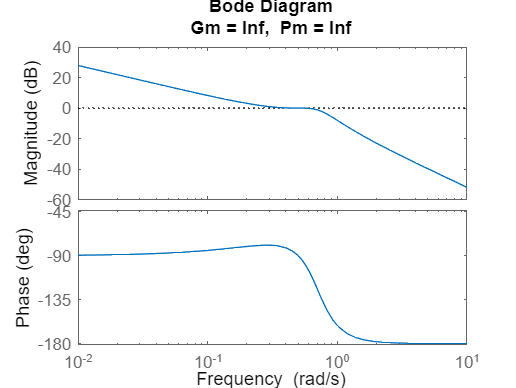

zapas_modulu = Inf

zapas_fazy = Inf

zapasy(G4, k4, 0, beta);

beta = 1

beta = 1

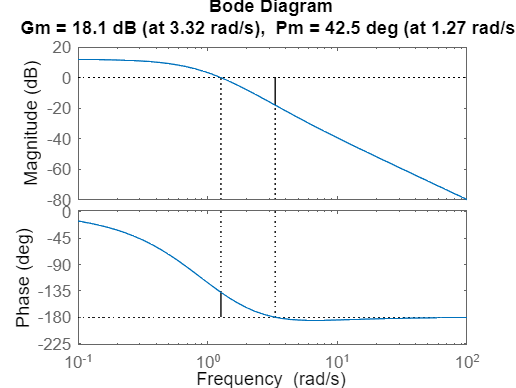

zapas_modulu = 7.9956

zapas_fazy = 42.5031

zapasy(G1, k1, 0, beta);

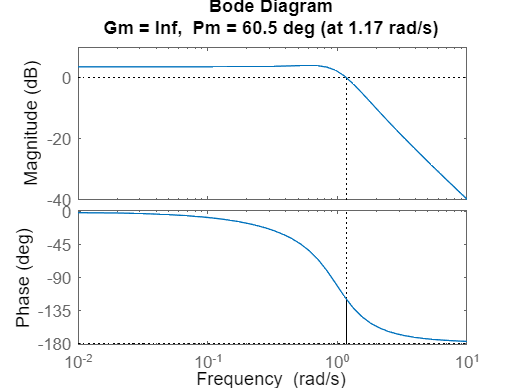

zapas_modulu = Inf

zapas_fazy = 60.5323

zapasy(G2, k2, 0, beta);

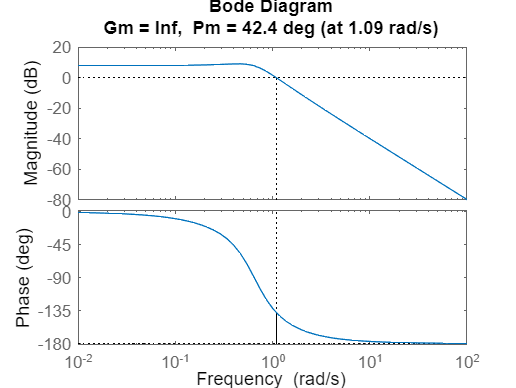

zapas_modulu = Inf

zapas_fazy = 42.4144

zapasy(G3, k3, 0, beta);

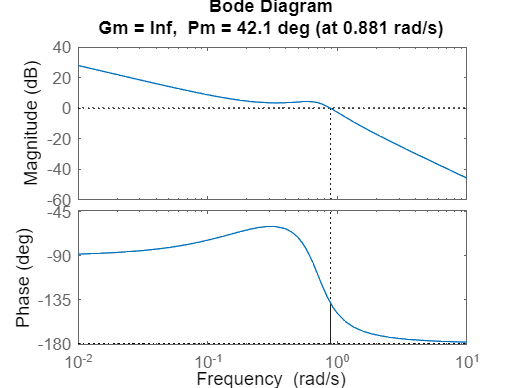

zapas_modulu = Inf

zapas_fazy = 42.0872

zapasy(G4, k4, 0, beta);

alfa = 0.1

alfa = 0.1000

beta = 0.5

beta = 0.5000

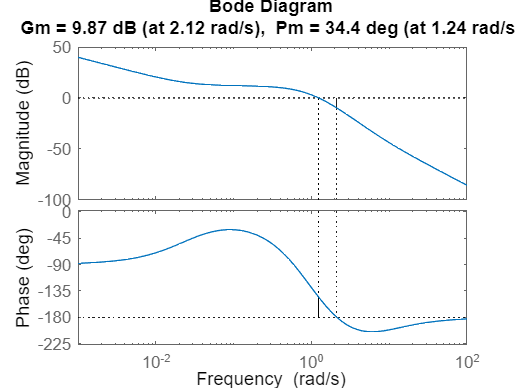

zapas_modulu = 3.1160

zapas_fazy = 34.3903

zapasy(G1, k1, alfa, beta);

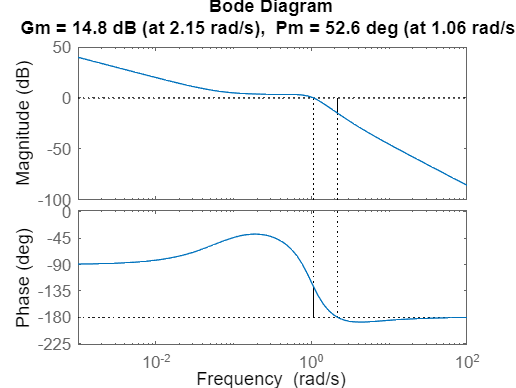

zapas_modulu = 5.5245

zapas_fazy = 52.5602

zapasy(G2, k2, alfa, beta);

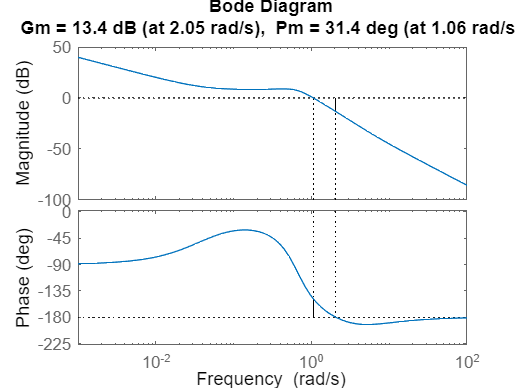

zapas_modulu = 4.6619

zapas_fazy = 31.3695

zapasy(G3, k3, alfa, beta);

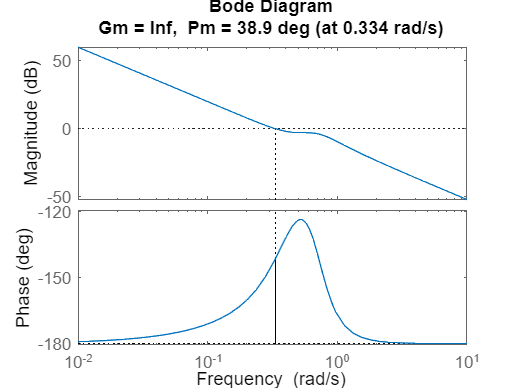

zapas_modulu = 0

zapas_fazy = 38.8882

zapasy(G4, k4, alfa, beta);

alfa = 1

alfa = 1

beta = 0.5

beta = 0.5000

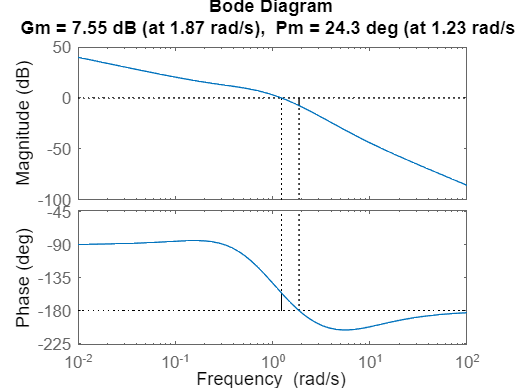

zapas_modulu = 2.3852

zapas_fazy = 24.3104

zapasy(G1, k1, alfa, beta);

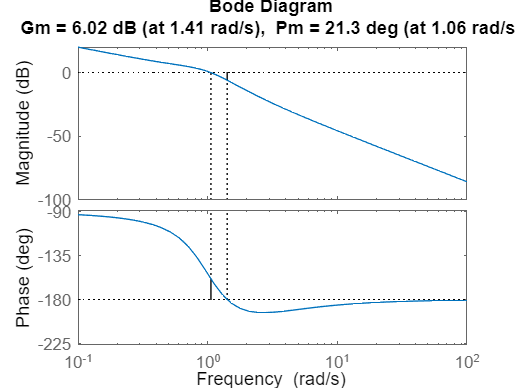

zapas_modulu = 2.0000

zapas_fazy = 21.2510

zapasy(G2, k2, alfa, beta);

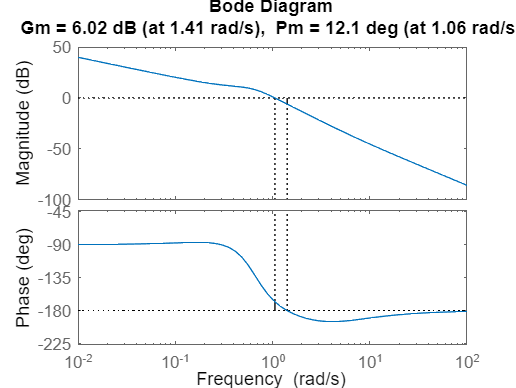

zapas_modulu = 1.9989

zapas_fazy = 12.1106

zapasy(G3, k3, alfa, beta);

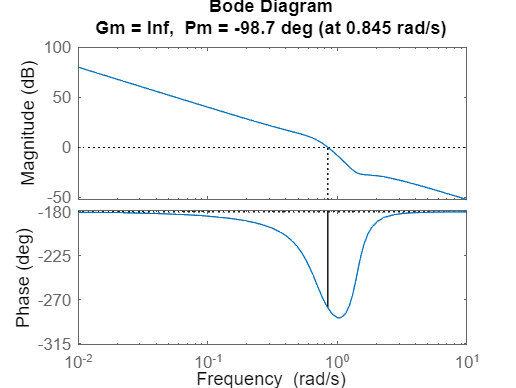

zapas_modulu = 0

zapas_fazy = -98.6901

zapasy(G4, k4, alfa, beta);

alfa = 0.1

alfa = 0.1000

beta = 1

beta = 1

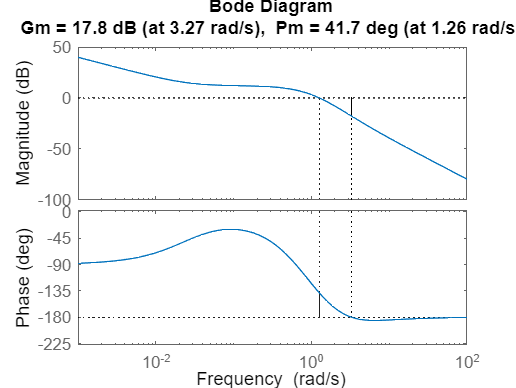

zapas_modulu = 7.7778

zapas_fazy = 41.6767

zapasy(G1, k1, alfa, beta);

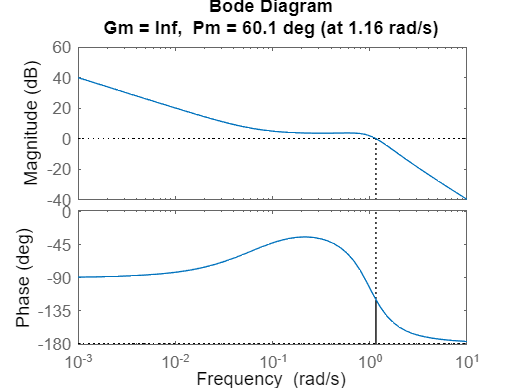

zapas_modulu = Inf

zapas_fazy = 60.0626

zapasy(G2, k2, alfa, beta);

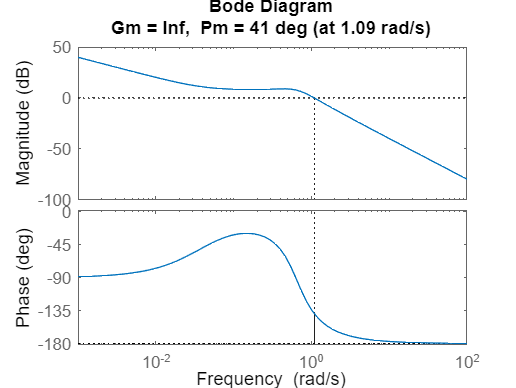

zapas_modulu = Inf

zapas_fazy = 40.9998

zapasy(G3, k3, alfa, beta);

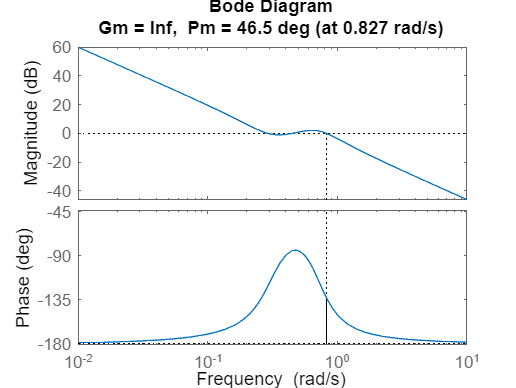

zapas_modulu = 0

zapas_fazy = 46.4855

zapasy(G4, k4, alfa, beta);

alfa = 1

alfa = 1

beta = 1

beta = 1

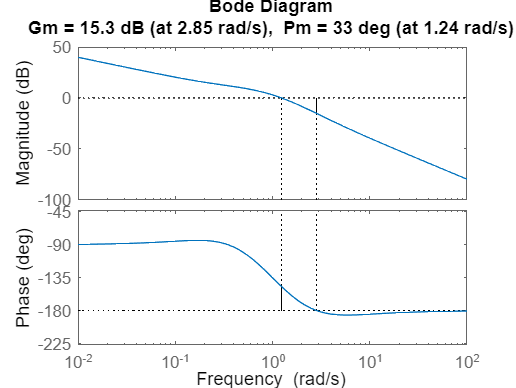

zapas_modulu = 5.8400

zapas_fazy = 32.9823

zapasy(G1, k1, alfa, beta);

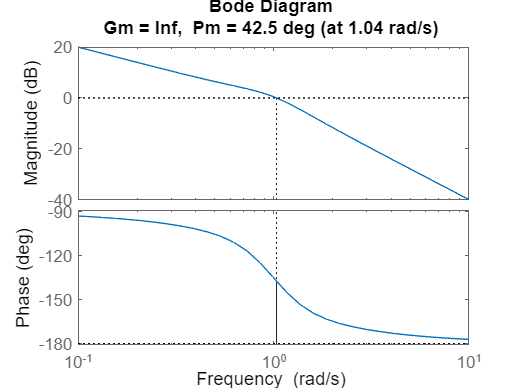

zapas_modulu = Inf

zapas_fazy = 42.4687

zapasy(G2, k2, alfa, beta);

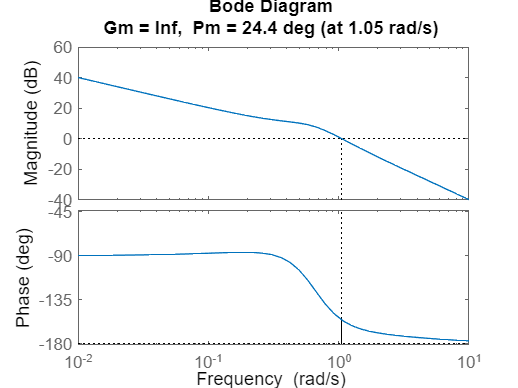

zapas_modulu = Inf

zapas_fazy = 24.3700

zapasy(G3, k3, alfa, beta);

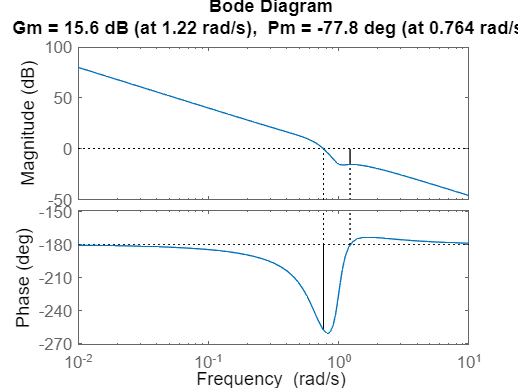

zapas_modulu = 6.0000

zapas_fazy = -77.7540

zapasy(G4, k4, alfa, beta);

function [] = zapasy(G, k, alfa, beta)
    Gr = tf([k], [1]) + tf([0 alfa], [1 0]) + tf([beta 0], [0 1]);
    margin(series(G, Gr))
    [Gm, Pm] = margin(series(G, Gr));
    zapas_modulu = Gm
    zapas_fazy = Pm
end

**Wnioski**

Udało się przeanalizować wpływ parametrów regulatora PID na wartości zapasów stabilności fazy. Wzrost wzmocnienia pogarsza stabilność, wzrost stałej całkowania zazwyczaj pogarsza stabilność, wzrost stałej różniczkowania poprawia stabilność jeśli jest niewielkie, jednak stała równa 1 była zbyt duża.